num2 = [0 0 2];
den2 = [1 5 3];
% Tiempo de muestreo
Ts = 1;
[nu1,de1]=c2dm(num2,den2,Ts);
% Función de transferencia discreta

sys = tf(nu1,de1,Ts)

sys =
 
     0.2722 z + 0.05792
  -------------------------
  z^2 - 0.5115 z + 0.006738
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties


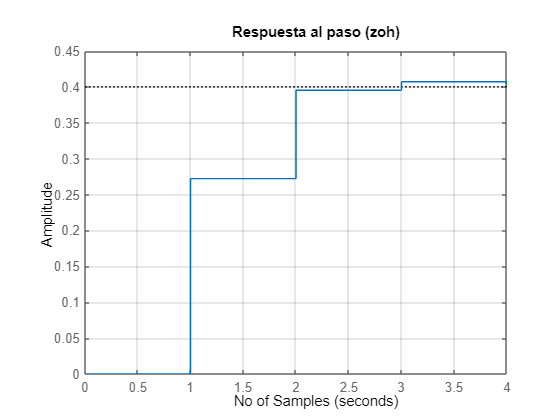

% Lazo cerrado
[nc1,dc1]=cloop(nu1,de1,-1);
dstep(nc1,dc1), title('Respuesta al paso (zoh)'), xlabel('No of Samples'),axis([0 4 0 0.45]), grid on

**Ejemplo 2:**

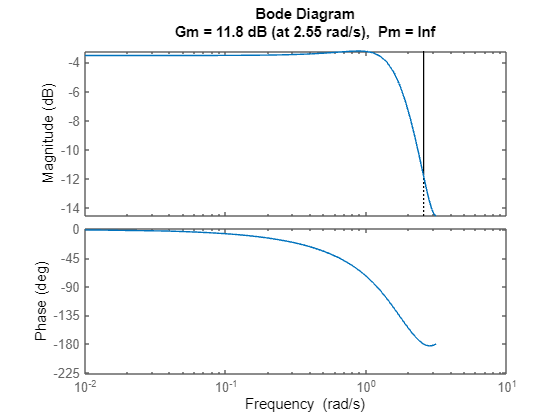

num2 = [0 0 2];
den2 = [1 2 3];
% Tiempo de muestreo
Ts2 = 1;
[n,c]=c2dm(num2,den2,Ts2);
% Función de transferencia discreta

[mag,fase,w] = dbode(n,c,Ts2);
margin(mag,fase,w)

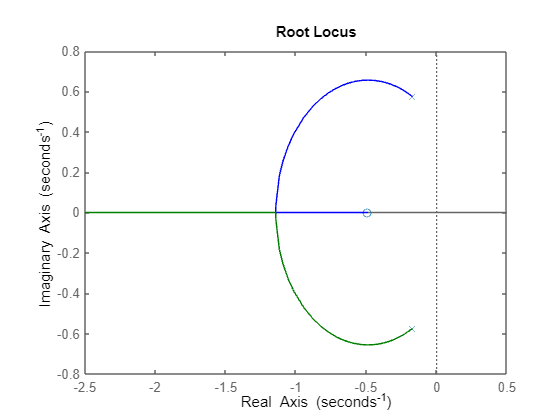

% Lazo cerrado
[nc2,dc2] = cloop(n,c);
rlocus(nc2,dc2)

**Respuesta en lazo cerrado a step**

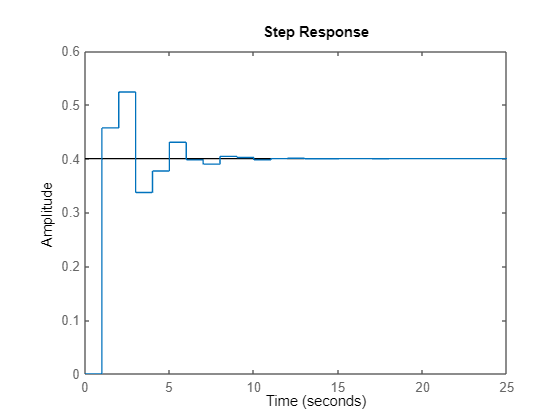

dstep(nc2,dc2)